syms m M l g F1 F2 t
syms x(t) theta(t)
dthetadt = diff(theta(t), t)

$$dthetadt = \frac{\partial }{\partial t}\theta \left(t\right)$$

dxdt = diff(x(t),t)

$$dxdt = \frac{\partial }{\partial t}x\left(t\right)$$

Tvozik = 1/2*M*dxdt^2;
Vvozik = 0;
dvx = -l*cos(theta)*dthetadt+dxdt;
dvy = l*sin(theta)*dthetadt;
Tkyvadlo = 1/2*m*(dvx^2+dvy^2);
Vkyvadlo = -m*g*l*cos(theta);
T = Tvozik +Tkyvadlo

$$T(t) = \frac{m\,\left({\left(\frac{\partial }{\partial t}x\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{2}+\frac{M\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}$$

V = Vvozik + Vkyvadlo

$$V(t) = -g\,l\,m\,\cos\left(\theta \left(t\right)\right)$$

% T = 1/2*M*dxdt^2+1/2*m*(dthetadt*l*cos(theta)+dxdt)^2
% V = -m*g*l*cos(theta)
% T=  1/2*M*dxdt^2+1/2*m*(dthetadt^2*l^2+2*cos(theta)*dthetadt*dxdt*l+dxdt^2)
% V = -m*g*l*cos(theta)
L = T - V

$$L(t) = \frac{m\,\left({\left(\frac{\partial }{\partial t}x\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{2}+\frac{M\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}+g\,l\,m\,\cos\left(\theta \left(t\right)\right)$$

D1 = diff(L,diff(x(t),t));
D2 = diff(L,x);
L1 = diff(D1,t) - D2 == F1;
L1 = simplify(L1)

$$L1(t) = l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+F_{1}=m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+M\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$


D3 = diff(L,diff(theta(t),t))

$$D3(t) = -\frac{m\,\left(l\,\cos\left(\theta \left(t\right)\right)\,\left(\frac{\partial }{\partial t}x\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,2-2\,l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}{2}$$

D4 = diff(L,theta)

$$D4(t) = \frac{m\,\left(2\,l\,\sin\left(\theta \left(t\right)\right)\,\left(\frac{\partial }{\partial t}x\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+2\,l^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{2}-g\,l\,m\,\sin\left(\theta \left(t\right)\right)$$

L2 = diff(D3,t) - D4 == F2;
L2 = simplify(L2)

$$L2(t) = m\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+g\,m\,\sin\left(\theta \left(t\right)\right)\,l=l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+F_{2}$$

%% load variables
g = 9.81;
l=0.35;
m = 0.25;
M = 2;
Q1 = 0; %moment dronu
Q2 = 0; %moment kyvadla

%%   
syms x1 x2 x3 x4 t u1 u2
% f1 = x2
% f2 = (l*m*sin(x3)*x4^2+u1-l*m*cos(x3)*0)/(m+M)
% f3 = x4
% f4 = (u2-g*l*m*sin(x3)-0*l*m*cos(x3)+l^2*m*cos(x3)*sin(x3)*x4^2)/(l^2*cos(x3)^2*m)

f1 = x2

$$f1 = x_{2}$$

f2 = (l*m*sin(x3)*x4^2+u1-l*m*cos(x3)*0)/(m+M)

$$f2 = \frac{7\,\sin\left(x_{3}\right)\,{x_{4}}^{2}}{180}+\frac{4\,u_{1}}{9}$$

f3 = x4

$$f3 = x_{4}$$

f4 = (-g*l*m*sin(x3)-0*l*m*cos(x3))/(l^2*m)

$$f4 = -\frac{981\,\sin\left(x_{3}\right)}{35}$$

% Calculate the Jacobians
J_A = jacobian([f1,f2,f3,f4],[x1, x2, x3, x4])

$$J\_A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{7\,{x_{4}}^{2}\,\cos\left(x_{3}\right)}{180} & \frac{7\,x_{4}\,\sin\left(x_{3}\right)}{90}\\ 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{981\,\cos\left(x_{3}\right)}{35} & 0 \end{array}\right)$$

J_B = jacobian([f1,f2,f3,f4],[u1])

$$J\_B = \left(\begin{array}{c} 0\\ \frac{4}{9}\\ 0\\ 0 \end{array}\right)$$


% Substitute all symbolic variables
subs_J_A = subs(J_A, [x1, x2, x3, x4, u1, g, l, m, M], [0, 0, 0, 0, 0, g, l, m, M])

$$subs\_J\_A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{981}{35} & 0 \end{array}\right)$$

subs_J_B = subs(J_B, [x1, x2, x3, x4, u1, g, l, m, M], [0, 0, 0, 0, 0, g, l, m, M])

$$subs\_J\_B = \left(\begin{array}{c} 0\\ \frac{4}{9}\\ 0\\ 0 \end{array}\right)$$


% Convert to double
A = double(subs_J_A)

A =          0    1.0000         0         0
         0         0         0         0
         0         0         0    1.0000
         0         0  -28.0286         0


B = double(subs_J_B)

B =          0
    0.4444
         0
         0



% Check controllability
rank(ctrb(A,B))

ans = 2

%% Deriving the Inverse Dynamics %%

%symbolic variables
syms m M l I t g u;
syms x dx ddx theta dtheta ddtheta;

%state of pole COM
xPole = x + l*sin(theta);
yPole = -l*cos(theta);
dxPole = dx + l*cos(theta)*dtheta

$$dxPole = \mathrm{dx}+\mathrm{dtheta}\,l\,\cos\left(\theta \right)$$

dyPole = l*sin(theta)*dtheta

$$dyPole = \mathrm{dtheta}\,l\,\sin\left(\theta \right)$$


%% Lagrangian %%
%kinetic energy
Tcart = M*dx^2 / 2;
Tpole = (m*((dxPole^2) + (dyPole^2))) / 2

$$Tpole = \frac{m\,\left({\left(\mathrm{dx}+\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)}^{2}+{\mathrm{dtheta}}^{2}\,l^{2}\,{\sin\left(\theta \right)}^{2}\right)}{2}$$

T = Tcart + Tpole

$$T = \frac{M\,{\mathrm{dx}}^{2}}{2}+\frac{m\,\left({\left(\mathrm{dx}+\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)}^{2}+{\mathrm{dtheta}}^{2}\,l^{2}\,{\sin\left(\theta \right)}^{2}\right)}{2}$$


%potential energy
Ucart = 0

Ucart = 0

Upole = m*g*yPole

$$Upole = -g\,l\,m\,\cos\left(\theta \right)$$

U = Ucart + Upole

$$U = -g\,l\,m\,\cos\left(\theta \right)$$


%lagrangian
L = simplify(T-U)

$$L = \frac{M\,{\mathrm{dx}}^{2}}{2}+\frac{{\mathrm{dx}}^{2}\,m}{2}+\frac{{\mathrm{dtheta}}^{2}\,l^{2}\,m}{2}+g\,l\,m\,\cos\left(\theta \right)+\mathrm{dtheta}\,\mathrm{dx}\,l\,m\,\cos\left(\theta \right)$$


%inverse dynamics
q = [x; theta]; %generalized coordinates
dq = [dx; dtheta];
ddq = [ddx; ddtheta];
F = [u;0];

dLddq = jacobian(L,dq);
dLdq = jacobian(L,q);
ddtdLddq = jacobian(dLddq,dq)*ddq + jacobian(dLddq,q)*dq;

%Equations of Motion
EOM = ddtdLddq - transpose(dLdq) - F;
solution = solve(EOM,ddq)

solution = struct with fields:
        ddx: (l*m*sin(theta)*dtheta^2 + u + g*m*cos(theta)*sin(theta))/(- m*cos(theta)^2 + M + m)
    ddtheta: -(l*m*cos(theta)*sin(theta)*dtheta^2 + u*cos(theta) + g*m*sin(theta) + M*g*sin(theta))/(l*(- m*cos(theta)^2 + M + m))



ddxSolution = simplify(solution.ddx)

$$ddxSolution = \frac{l\,m\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+u+g\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{-m\,{\cos\left(\theta \right)}^{2}+M+m}$$

ddthetaSolution = simplify(solution.ddtheta)

$$ddthetaSolution = -\frac{l\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+u\,\cos\left(\theta \right)+g\,m\,\sin\left(\theta \right)+M\,g\,\sin\left(\theta \right)}{l\,\left(-m\,{\cos\left(\theta \right)}^{2}+M+m\right)}$$

% ddxSolution = subs(ddxSolution,'m',0.1);
% ddxSolution = subs(ddxSolution,'M',1);
% ddxSolution = subs(ddxSolution,'l',1);
% ddxSolution = subs(ddxSolution,'g',-9.81);
% ddthetaSolution = subs(ddthetaSolution,'m',0.1);
% ddthetaSolution = subs(ddthetaSolution,'M',1);
% ddthetaSolution = subs(ddthetaSolution,'l',1);
% ddthetaSolution = subs(ddthetaSolution,'g',-9.81);

%Standard Form
H = [M+m l*m*cos(theta); l*m*cos(theta) l^2*m];
C = [0 -l*m*sin(theta)*dtheta; 0 0];
G = [0; -g*l*m*sin(theta)];
B = [1;0];


syms m M l I t g u;
syms x dx ddx theta dtheta ddtheta;

%without tangent velocity of the load
Tvozik = 1/2*M*dx^2;
Vvozik = 0;
dvx = -l*cos(theta)*dtheta+dx;
dvy = l*sin(theta)*dtheta;
Tkyvadlo = 1/2*m*((dvx^2)+(dvy^2));
Vkyvadlo = -m*g*l*cos(theta);
T = Tvozik +Tkyvadlo 

$$T = \frac{M\,{\mathrm{dx}}^{2}}{2}+\frac{m\,\left({\left(\mathrm{dx}-\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)}^{2}+{\mathrm{dtheta}}^{2}\,l^{2}\,{\sin\left(\theta \right)}^{2}\right)}{2}$$

V = Vvozik + Vkyvadlo

$$V = -g\,l\,m\,\cos\left(\theta \right)$$


%with tangent velocity of the load
%T = 1/2*M*dx^2+1/2*m*(dtheta*l*cos(theta)+dx)^2
%V = -m*g*l*cos(theta)

% T=  1/2*M*dxdt^2+1/2*m*(dthetadt^2*l^2+2*cos(theta)*dthetadt*dxdt*l+dxdt^2)
% V = -m*g*l*cos(theta)
L = T - V

$$L = \frac{M\,{\mathrm{dx}}^{2}}{2}+\frac{m\,\left({\left(\mathrm{dx}-\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)}^{2}+{\mathrm{dtheta}}^{2}\,l^{2}\,{\sin\left(\theta \right)}^{2}\right)}{2}+g\,l\,m\,\cos\left(\theta \right)$$

% D1 = diff(L,diff(x(t),t));
% D2 = diff(L,x);
% L1 = diff(D1,t) - D2 == F1;
% L1 = simplify(L1)
% 
% D3 = diff(L,diff(theta(t),t))
% D4 = diff(L,theta)
% L2 = diff(D3,t) - D4 == F2;
% L2 = simplify(L2)


q = [x; theta]; %generalized coordinates
dq = [dx; dtheta];
ddq = [ddx; ddtheta];
F = [u;0];

dLddq = jacobian(L,dq)

$$dLddq = \left(\begin{array}{cc} M\,\mathrm{dx}+\frac{m\,\left(2\,\mathrm{dx}-2\,\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)}{2} & -\frac{m\,\left(2\,l\,\cos\left(\theta \right)\,\left(\mathrm{dx}-\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)-2\,\mathrm{dtheta}\,l^{2}\,{\sin\left(\theta \right)}^{2}\right)}{2} \end{array}\right)$$

dLdq = jacobian(L,q)

$$dLdq = \left(\begin{array}{cc} 0 & \frac{m\,\left(2\,{\mathrm{dtheta}}^{2}\,l^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)+2\,\mathrm{dtheta}\,l\,\sin\left(\theta \right)\,\left(\mathrm{dx}-\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)\right)}{2}-g\,l\,m\,\sin\left(\theta \right) \end{array}\right)$$

%chain rule of derivation with respect to time
ddtdLddq = jacobian(dLddq,dq)*ddq + jacobian(dLddq,q)*dq

$$ddtdLddq = \left(\begin{array}{c} l\,m\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+\mathrm{ddx}\,\left(M+m\right)-\mathrm{ddtheta}\,l\,m\,\cos\left(\theta \right)\\ \frac{\mathrm{dtheta}\,m\,\left(2\,l\,\sin\left(\theta \right)\,\left(\mathrm{dx}-\mathrm{dtheta}\,l\,\cos\left(\theta \right)\right)+2\,\mathrm{dtheta}\,l^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)\right)}{2}+\frac{\mathrm{ddtheta}\,m\,\left(2\,l^{2}\,{\cos\left(\theta \right)}^{2}+2\,l^{2}\,{\sin\left(\theta \right)}^{2}\right)}{2}-\mathrm{ddx}\,l\,m\,\cos\left(\theta \right) \end{array}\right)$$


%Equations of Motion
EOM = ddtdLddq - transpose(dLdq) - F;
adadsd = simplify(EOM)

$$adadsd = \left(\begin{array}{c} l\,m\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}-u+\mathrm{ddx}\,\left(M+m\right)-\mathrm{ddtheta}\,l\,m\,\cos\left(\theta \right)\\ l\,m\,\left(\mathrm{ddtheta}\,l-\mathrm{ddx}\,\cos\left(\theta \right)+g\,\sin\left(\theta \right)\right) \end{array}\right)$$

solution = solve(EOM,ddq)

solution = struct with fields:
        ddx: -(dtheta^2*l*m*sin(theta)^3 - u*sin(theta)^2 - u*cos(theta)^2 + g*m*cos(theta)*sin(theta) + dtheta^2*l*m*cos(theta)^2*sin(theta))/(m*sin(theta)^2 + M*cos(theta)^2 + M*sin(theta)^2)
    ddtheta: -(l*m*cos(theta)*sin(theta)*dtheta^2 - u*cos(theta) + g*m*sin(theta) + M*g*sin(theta))/(M*l*cos(theta)^2 + M*l*sin(theta)^2 + l*m*sin(theta)^2)



ddxSolution = simplify(solution.ddx)

$$ddxSolution = -\frac{l\,m\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}-u+g\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{-m\,{\cos\left(\theta \right)}^{2}+M+m}$$

ddthetaSolution = simplify(solution.ddtheta)

$$ddthetaSolution = -\frac{l\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}-u\,\cos\left(\theta \right)+g\,m\,\sin\left(\theta \right)+M\,g\,\sin\left(\theta \right)}{l\,\left(-m\,{\cos\left(\theta \right)}^{2}+M+m\right)}$$

syms x1 x2 x3 x4 t u g m l M
g = 9.81;
l=0.35;
m = 0.25;
M = 2;
f1 = x2

$$f1 = x_{2}$$

f2 = (-l*m*sin(x3)*x4^2+u-m*g*cos(x3)*sin(x3))/(-m*cos(x3)^2+M+m)

$$f2 = \frac{\frac{7\,\sin\left(x_{3}\right)\,{x_{4}}^{2}}{80}-u+\frac{981\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{400}}{\frac{{\cos\left(x_{3}\right)}^{2}}{4}-\frac{9}{4}}$$

f3 = x4

$$f3 = x_{4}$$

f4 = (-l*m*cos(x3)*sin(x3)*x4^2+u*cos(x3)-g*m*sin(x3)-M*g*sin(x3))/(l*(-m*cos(x3)^2+M+m))

$$f4 = \frac{\frac{7\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\,{x_{4}}^{2}}{80}+\frac{8829\,\sin\left(x_{3}\right)}{400}-u\,\cos\left(x_{3}\right)}{\frac{7\,{\cos\left(x_{3}\right)}^{2}}{80}-\frac{63}{80}}$$


%version with tangent velocity of load
%f2 = (u * cos(x3) + g * m * sin(x3)) / (M * cos(x3));
%f3= (-(-M*l*cos(x3)*sin(x3)*x4^2 + u*cos(x3) + g*m*sin(x3) + M*g*sin(x3))) / (M*l*cos(x3)^2);

% Calculate the Jacobians
J_A = jacobian([f1,f2,f3,f4],[x1, x2, x3, x4])

$$J\_A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{\frac{7\,{x_{4}}^{2}\,\cos\left(x_{3}\right)}{80}+\frac{981\,{\cos\left(x_{3}\right)}^{2}}{400}-\frac{981\,{\sin\left(x_{3}\right)}^{2}}{400}}{\sigma_{2}}+\frac{\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\,\left(\frac{7\,\sin\left(x_{3}\right)\,{x_{4}}^{2}}{80}-u+\frac{981\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{400}\right)}{2\,{\sigma_{2}}^{2}} & \frac{7\,x_{4}\,\sin\left(x_{3}\right)}{40\,\sigma_{2}}\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{\frac{7\,{x_{4}}^{2}\,{\cos\left(x_{3}\right)}^{2}}{80}-\frac{7\,{x_{4}}^{2}\,{\sin\left(x_{3}\right)}^{2}}{80}+\frac{8829\,\cos\left(x_{3}\right)}{400}+u\,\sin\left(x_{3}\right)}{\sigma_{1}}+\frac{7\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\,\left(\frac{7\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\,{x_{4}}^{2}}{80}+\frac{8829\,\sin\left(x_{3}\right)}{400}-u\,\cos\left(x_{3}\right)\right)}{40\,{\sigma_{1}}^{2}} & \frac{7\,x_{4}\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{40\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{7\,{\cos\left(x_{3}\right)}^{2}}{80}-\frac{63}{80}\\ \sigma_{2}=\frac{{\cos\left(x_{3}\right)}^{2}}{4}-\frac{9}{4} \end{array}$$

J_B = jacobian([f1,f2,f3,f4],[u])

$$J\_B = \left(\begin{array}{c} 0\\ -\frac{1}{\frac{{\cos\left(x_{3}\right)}^{2}}{4}-\frac{9}{4}}\\ 0\\ -\frac{\cos\left(x_{3}\right)}{\frac{7\,{\cos\left(x_{3}\right)}^{2}}{80}-\frac{63}{80}} \end{array}\right)$$


% Substitute all symbolic variables
subs_J_A = subs(J_A, [x1, x2, x3, x4, u, g, l, m, M], [0, 0, 0, 0, 0, g, l, m, M])

$$subs\_J\_A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{981}{800} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{8829}{280} & 0 \end{array}\right)$$

subs_J_B = subs(J_B, [x1, x2, x3, x4, u, g, l, m, M], [0, 0, 0, 0, 0, g, l, m, M])

$$subs\_J\_B = \left(\begin{array}{c} 0\\ \frac{1}{2}\\ 0\\ \frac{10}{7} \end{array}\right)$$


% Convert to double
A = double(subs_J_A)

A =          0    1.0000         0         0
         0         0   -1.2263         0
         0         0         0    1.0000
         0         0  -31.5321         0


B = double(subs_J_B)

B =          0
    0.5000
         0
    1.4286



C = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D=[0;0;0;0]

D =      0
     0
     0
     0



% Check controllability
rank(ctrb(A,B))

ans = 4

ctrb(A,B)

ans =          0    0.5000         0   -1.7518
    0.5000         0   -1.7518         0
         0    1.4286         0  -45.0459
    1.4286         0  -45.0459         0


% Your continuous-time state-space system
sys = ss(A, B, C, D);

Ts = 0.02; %  milliseconds

sys_d = c2d(sys, Ts, ['zoh'])

sys_d =
 
  A = 
               x1          x2          x3          x4
   x1           1        0.02   -0.000245  -1.634e-06
   x2           0           1    -0.02447   -0.000245
   x3           0           0      0.9937     0.01996
   x4           0           0     -0.6293      0.9937
 
  B = 
              u1
   x1  9.999e-05
   x2   0.009998
   x3  0.0002854
   x4    0.02851
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Sample time: 0.02 seconds
Discrete-time state-space model.



A_d = sys_d.A

A_d =     1.0000    0.0200   -0.0002   -0.0000
         0    1.0000   -0.0245   -0.0002
         0         0    0.9937    0.0200
         0         0   -0.6293    0.9937


B_d = sys_d.B

B_d =     0.0001
    0.0100
    0.0003
    0.0285


%plot

figure;
plot(out.linearTheta.Time,out.linearTheta.Data);

Unable to resolve the name 'out.linearTheta.Time'.

grid on;
hold on;
plot(out.nonLinearTheta.Time,out.nonLinearTheta.Data);
legend("linearizovaný model", "nelineární model")
title("Validace modelu")
xlabel("čas [s]")
ylabel("\theta [rad]")

figure;
plot(out.linearTheta.Time,out.linearTheta.Data);
grid on;
hold on;
plot(out.nonLinearTheta.Time,out.nonLinearTheta.Data);
legend("linearizovaný model", "nelineární model")
title("Validace řízení")
xlabel("čas [s]")
ylabel("\theta' [rad \cdot s^{-1}]")

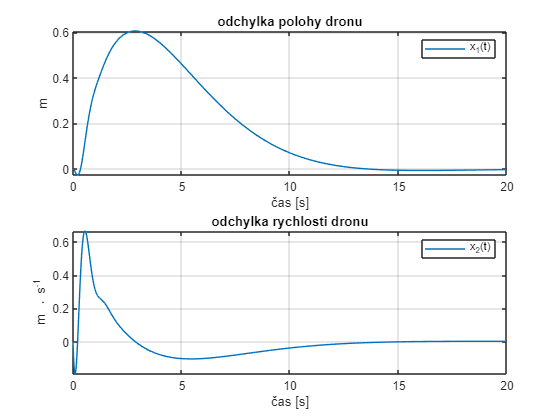

%plot

x1_plot = out.simout.Data(:,1);
x2_plot = out.simout.Data(:,2);
x3_plot = out.simout.Data(:,3);
x4_plot = out.simout.Data(:,4);
% První figura s x1 a x2
figure;

% Graf pro x1
subplot(2,1,1);
plot(out.simout.Time, x1_plot);
grid on;
legend("x_1(t)")
title("odchylka polohy dronu")
xlabel("čas [s]")
ylabel("m")

% Graf pro x2
subplot(2,1,2);
plot(out.simout.Time, x2_plot);
grid on;
legend("x_2(t)")
title("odchylka rychlosti dronu")
xlabel("čas [s]")
ylabel("m \cdot s^{-1}")

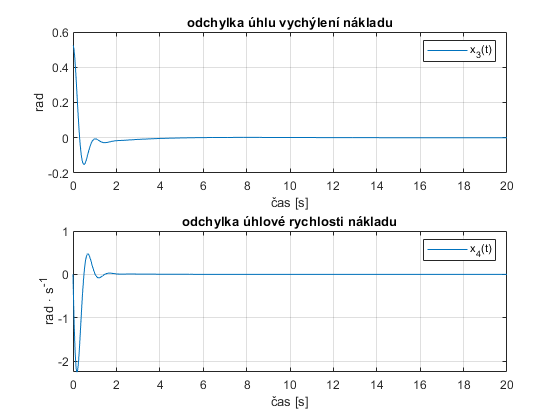


% Druhá figura s x3 a x4
figure;

% Graf pro x3
subplot(2,1,1);
plot(out.simout.Time, x3_plot);
grid on;
legend("x_3(t)")
title("odchylka úhlu vychýlení nákladu")
xlabel("čas [s]")
ylabel("rad")

% Graf pro x4
subplot(2,1,2);
plot(out.simout.Time, x4_plot);
grid on;
legend("x_4(t)")
title("odchylka úhlové rychlosti nákladu")
xlabel("čas [s]")
ylabel("rad \cdot s^{-1}")

if rank(ctrb(A_d,B_d))==4
    disp('System is controllable');
else
    disp('System is not controllable');
end

System is controllable


x1max = 4;
x2max = 2.0;
x3max = pi/35;
x4max = 1.5;
u1max = 2.4;
%LQR Controller
Q = [1/(x1max)^2 0 0 0; 0 1/(x2max)^2 0 0; 0 0 1/(x3max)^2 0; 0 0 0 1/(x4max)^2] %cost on states

Q =     0.0625         0         0         0
         0    0.2500         0         0
         0         0  124.1184         0
         0         0         0    0.4444


R = 1/(u1max)^2 %cost on inputs

R = 0.1736

[K,S,E] = lqr(A,B,Q,R)

K =     0.6000    2.4554   15.4431    4.1056


S =     0.2558    0.3984    0.4277   -0.0665
    0.3984    1.5866    1.8167   -0.2569
    0.4277    1.8167   29.2603    1.2409
   -0.0665   -0.2569    1.2409    0.5889


E =   -0.3373 + 0.2377i
  -0.3373 - 0.2377i
  -3.2091 + 6.2527i
  -3.2091 - 6.2527i



% Now you can apply LQR on the discretized system
[K_d, S_d, E_d] = dlqr(A_d, B_d, Q, R)

K_d =     0.5589    2.2931   13.1042    3.9649


S_d = 1.0e+03 *

    0.0128    0.0199    0.0214   -0.0033
    0.0199    0.0795    0.0909   -0.0128
    0.0214    0.0909    1.5267    0.0620
   -0.0033   -0.0128    0.0620    0.0297


E_d =    0.9933 + 0.0047i
   0.9933 - 0.0047i
   0.9306 + 0.1170i
   0.9306 - 0.1170i



% Check the properties of the discretized system
eig(A_d - B_d * K_d)

ans =    0.9306 + 0.1170i
   0.9306 - 0.1170i
   0.9933 + 0.0047i
   0.9933 - 0.0047i
